cleanGPU();

load('stations.mat');

load ('tripsData201712.mat');

BD_myTripsData = tall(tripsData201712);

%Creation of histogram for Travel Time (Saved under graphics folder)
%histogram(BD_myTripsData.Travel_time_seconds,400,'BinLimits',[1,3000]);

Ar_stations = table2array(stations);

[num_stations,~] = size(Ar_stations);

StationsCombinationsNumber = nchoosek((Ar_stations(:,1))', 2);
myCombinations = array2table(StationsCombinationsNumber,'VariableNames',{'id','id_2'});

myCombinations = join(myCombinations,stations);
myCombinations.Properties.VariableNames{1} = 'id_origin';
myCombinations.Properties.VariableNames{2} = 'id';
myCombinations.Properties.VariableNames{3} = 'latitude_origin';
myCombinations.Properties.VariableNames{4} = 'longitude_origin';
myCombinations = join(myCombinations,stations);
myCombinations.Properties.VariableNames{2} = 'id_dest';
myCombinations.Properties.VariableNames{5} = 'latitude_dest';
myCombinations.Properties.VariableNames{6} = 'longitude_dest';

%Do not uncomment unless all combinations need to be recalculated using Google APIS (13 hours run-time)
%I had to remove my API key because every time this HTTP_Request runs, the cost is 140 USD for 30k Request.
%In case it has to be re-run please populate your own API key on the HTTP_Request.m file

%PreHTTPRequest = table2array(myCombinations);
%HTTP_Request

%Already calculated distances will be loaded instead of recalculated
%Do not keep previous two lines uncommented if the following lines are used.
load('table_AllCombinationsBetweenStations_GoogleData_Distance_Time.mat');

%Definition of Local Constants
MAX_NUMBER_STATIONS = 1000;

%It is required to create a new index so the two tables can be joined.
ConvertedCodeForRoutes = (table2array(BD_myTripsData(:,2))*MAX_NUMBER_STATIONS) + table2array(BD_myTripsData(:,3));
tb_ConvertedCodeForRoutes = array2table(ConvertedCodeForRoutes,'VariableNames',{'Route_Index'});
IndexedTableWithAllTrips = [tb_ConvertedCodeForRoutes, BD_myTripsData];

%And now the Database Of Stations Routes must match the same index defined before
%But before it is needed to take the assumption that travelling from A to B is the same as B to A.
%Therefore the Database of Stations Routes has to be expanded

AsumptionABBA = [DatabaseOfStationsRoutes(:,2),DatabaseOfStationsRoutes(:,1), DatabaseOfStationsRoutes(:,3:end)];
myArrayOfData = vertcat(table2array(DatabaseOfStationsRoutes),table2array(AsumptionABBA));

%Assignment of common index
myArrayOfData = [(myArrayOfData(:,1)*MAX_NUMBER_STATIONS) + (myArrayOfData(:,2)), myArrayOfData];
VariableNames = ['Route_Index', DatabaseOfStationsRoutes.Properties.VariableNames];
myTableOfStations = array2table(myArrayOfData,'VariableNames',VariableNames);

%Join both tables and see the magic occur, inner join will take only elements where A and B are different.
zOut_SingleTrips = innerjoin(IndexedTableWithAllTrips,myTableOfStations,'keys','Route_Index');

%For all the other elements that got excluded it is important to store them separately
Log_Index = IndexedTableWithAllTrips.Origen_Id == IndexedTableWithAllTrips.Destino_Id;
zOut_RoundTrips = IndexedTableWithAllTrips(Log_Index,IndexedTableWithAllTrips.Properties.VariableNames);

%The sum of elements of zOut_SingleTrips and zOut_RoundTrips should be the same
Size_Matches = gather(size(IndexedTableWithAllTrips) == size(zOut_RoundTrips) + size(zOut_SingleTrips));

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0 sec



if(Size_Matches(1))
    fprintf('Process completed succesfully.\n');
else
    fprintf('Process error. Size of Round Trips and Single trips dont match.\n');
end

Process completed succesfully.


Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0 sec


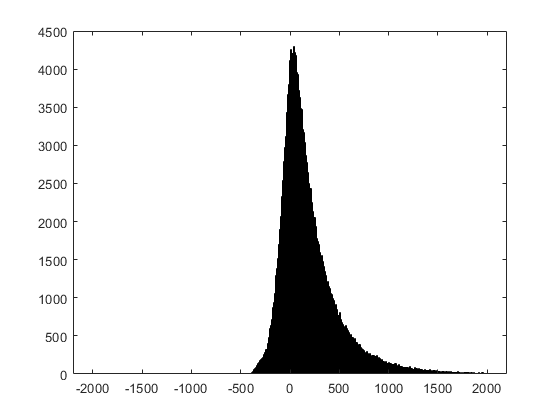

%Analysis Section
%Histogram for the difference between the time Google Calculated and the actual time.

travelTimeDifference = zOut_SingleTrips.Travel_time_seconds - zOut_SingleTrips.bicy_google_time;
h = histogram(travelTimeDifference,400,'BinLimits',[-500,2000]);